% Open the saved figure
fig_handle = openfig('TYPEA_pos2_single_length_no_additional_dmrs_scs60with_ce_no_log.fig')

fig_handle =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [667 224 560 420]
       Units: 'pixels'

  Show all properties


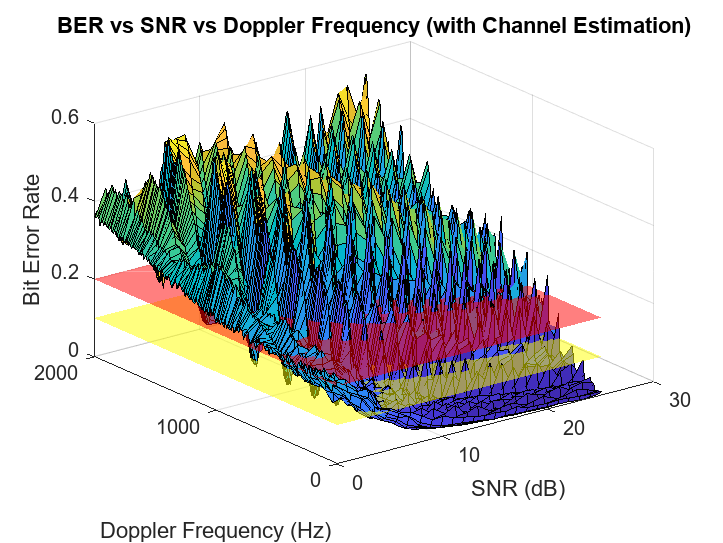


% Access the axes handle
ax = gca(fig_handle);


hold(ax, 'on'); % Allow multiple plots on the same axes

% Get the current axis limits
x_limits = xlim(ax);
y_limits = ylim(ax);

% Define the range for x and y coordinates
x_range = x_limits;
y_range = y_limits;

% Generate a grid of x and y coordinates covering the entire figure range
[x_grid, y_grid] = meshgrid(x_range, y_range);

% Generate z coordinates for the plane (constant at z = 0.1)
z_plane_1 = ones(size(x_grid)) * 0.1;
z_plane_2 = ones(size(x_grid)) * 0.2;

% Plot the plane
surf(ax, x_grid, y_grid, z_plane_1, 'FaceColor', 'y', 'EdgeColor', 'none', 'FaceAlpha', 0.5);
surf(ax, x_grid, y_grid, z_plane_2, 'FaceColor', "r", 'EdgeColor', 'none', 'FaceAlpha', 0.5);


% Adjust the transparency (alpha) and color of the plane as needed

% Specify the folder containing the saved figures
% folderPath = 'C:\Users\user\OneDrive - University of Cambridge\Documents\MATLAB\TypeA_initpos_array';
folderPath = 'C:\Users\user\OneDrive - University of Cambridge\Documents\MATLAB\log\initpos'

folderPath = 'C:\Users\user\OneDrive - University of Cambridge\Documents\MATLAB\log\initpos'

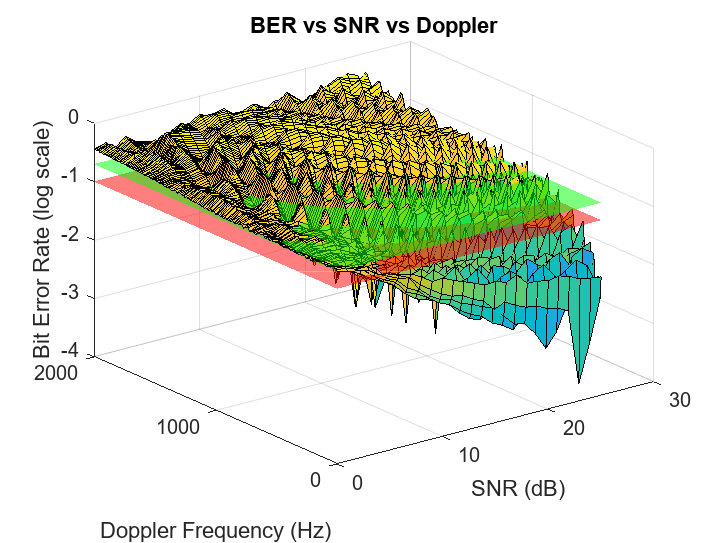

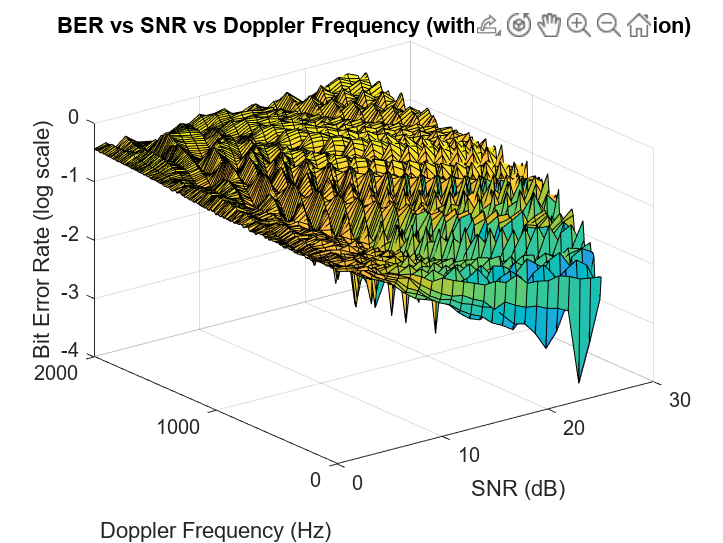

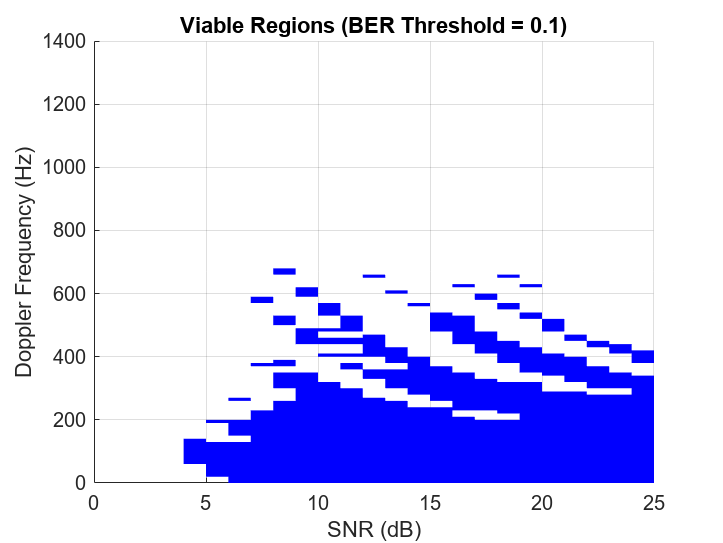

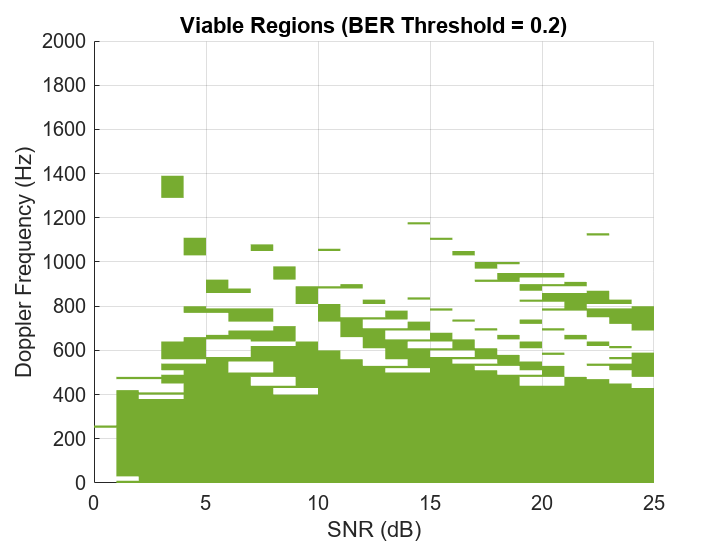

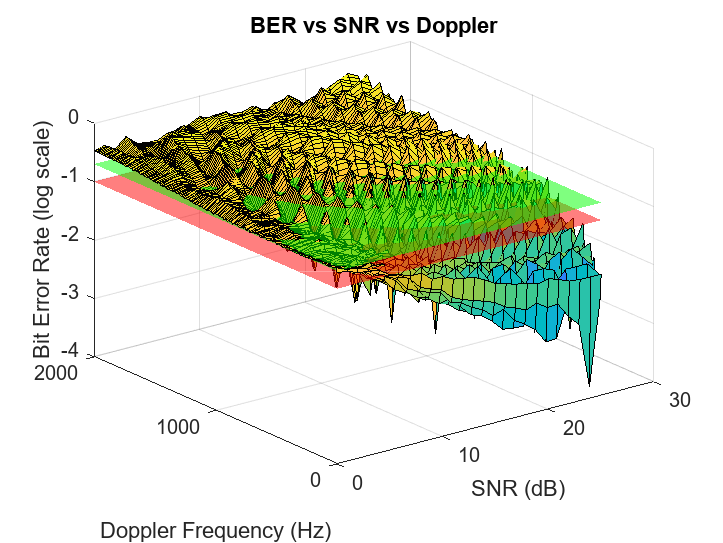

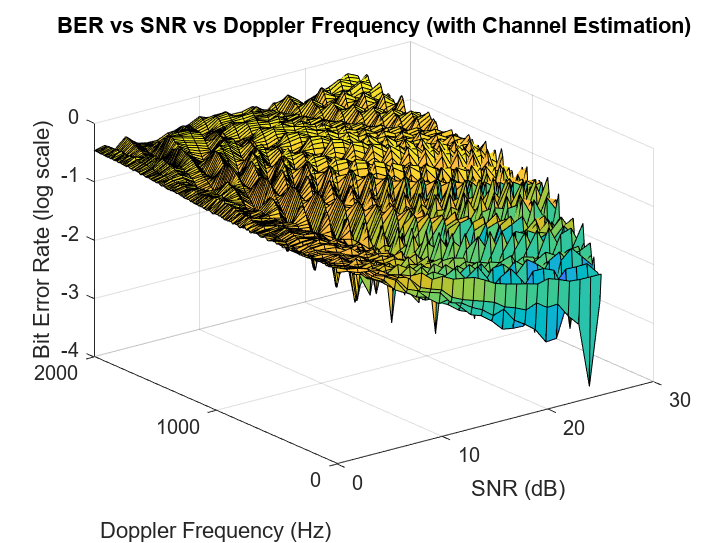

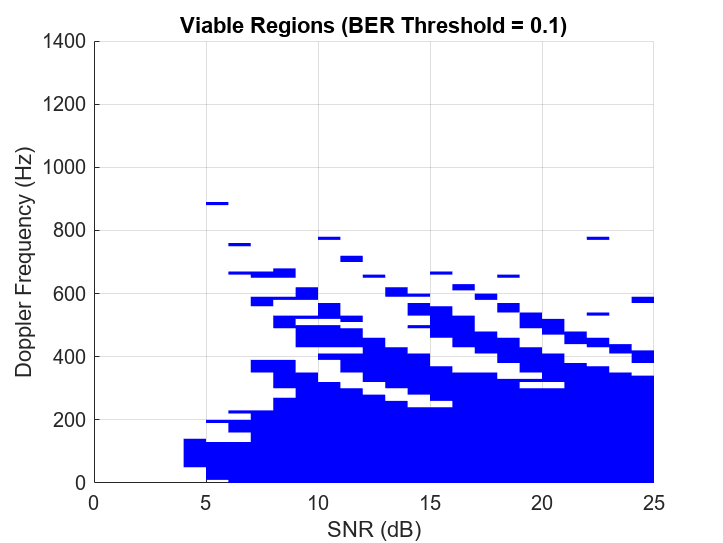

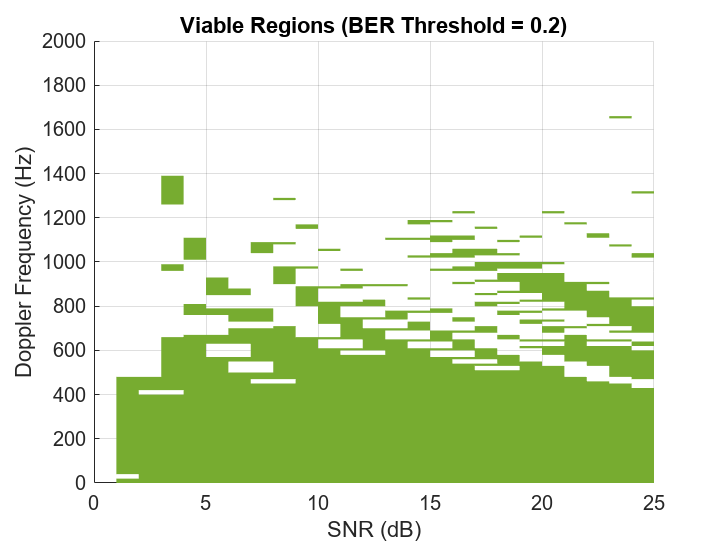

% List all files in the folder
files = dir(fullfile(folderPath, '*ce_log.fig'));

% Loop through each file
for i = 1:length(files)
    % Check if it's a figure file
    [~, ~, ext] = fileparts(files(i).name);
    if strcmpi(ext, '.fig')
        % Open the figure
        fig_handle = openfig(fullfile(folderPath, files(i).name));
        
        % Call the viable_region function with the figure handle
        add_plane(fig_handle, folderPath);
        
        fig_handle = openfig(fullfile(folderPath, files(i).name));
        viable_region_1(fig_handle, folderPath);
        viable_region_2(fig_handle, folderPath);

    end
end

function viable_region_1(fig_handle, folderPath)
    % Extract data from the surface plot assuming it's the first child
    surf_plots = findobj(fig_handle, 'Type', 'surface');
    x_data = surf_plots.XData;
    y_data = surf_plots.YData;
    z_data = surf_plots.ZData;
    
    % Create a new figure for the 2D plot
    figure;

    % Plot the 2D plot with z <= 0.1 in a different color
    z_data_other = z_data;
    z_data_other(z_data > log10(0.1)) = nan; % Set points > 0.1 to nan
    
    surf(x_data, y_data, z_data_other, 'FaceColor', 'b', 'EdgeColor', 'none');
    
    % Set the view to look from above
    view(0, 90);
    
    % Add labels, title, etc. as needed
    xlabel('SNR (dB)');
    ylabel('Doppler Frequency (Hz)');
    title('Viable Regions (BER Threshold = 0.1)');

    % Save the plot as PNG
    [~, fileName, ~] = fileparts(get(fig_handle, 'FileName'));
    saveas(gcf, fullfile(folderPath, [fileName, '_viable_region_1.png']));
end

function viable_region_2(fig_handle, folderPath)
    % Extract data from the surface plot assuming it's the first child
    surf_plots = findobj(fig_handle, 'Type', 'surface');
    x_data = surf_plots.XData;
    y_data = surf_plots.YData;
    z_data = surf_plots.ZData;
    
    % Create a new figure for the 2D plot
    figure;
        
    % Plot the 2D plot with z <= 0.2 in a different color
    z_data_other = z_data;
    z_data_other(z_data > log10(0.2)) = nan; % Set points > 0.2 to nan
    
    surf(x_data, y_data, z_data_other, 'FaceColor', "#77AC30", 'EdgeColor', 'none');
    
    % Set the view to look from above
    view(0, 90);
    
    % Add labels, title, etc. as needed
    xlabel('SNR (dB)');
    ylabel('Doppler Frequency (Hz)');
    title('Viable Regions (BER Threshold = 0.2)');
    
    % Save the plot as PNG
    [~, fileName, ~] = fileparts(get(fig_handle, 'FileName'));
    saveas(gcf, fullfile(folderPath, [fileName, '_viable_region_2.png']));
end

function add_plane(fig_handle, folderPath)
    % Access the axes handle
    ax = gca(fig_handle);
    
    
    hold(ax, 'on'); % Allow multiple plots on the same axes
    
    % Get the current axis limits
    x_limits = xlim(ax);
    y_limits = ylim(ax);
    
    % Define the range for x and y coordinates
    x_range = x_limits;
    y_range = y_limits;
    
    % Generate a grid of x and y coordinates covering the entire figure range
    [x_grid, y_grid] = meshgrid(x_range, y_range);
    
    % Generate z coordinates for the plane (constant at z = 0.1)
    z_plane_1 = ones(size(x_grid)) * log10(0.1);
    z_plane_2 = ones(size(x_grid)) * log10(0.2);
    
    % Plot the plane
    surf(ax, x_grid, y_grid, z_plane_1, 'FaceColor', 'r', 'EdgeColor', 'none', 'FaceAlpha', 0.5);
    surf(ax, x_grid, y_grid, z_plane_2, 'FaceColor', "g", 'EdgeColor', 'none', 'FaceAlpha', 0.5);
    
    % Change the title of the figure
    title(ax, 'BER vs SNR vs Doppler');

    % Adjust the transparency (alpha) and color of the plane as needed
    % Save the plot as PNG
    [~, fileName, ~] = fileparts(get(fig_handle, 'FileName'));
    saveas(gcf, fullfile(folderPath, [fileName, 'z_plane.png']));
end